Выполнил: Ногтев Семен

Цель работы: рассчитать потребную тягу, в зависимости от угла отклонения винтомоторной группы, с тем чтобы почувствовать, насколько в количественном выражении будет выигрыш в затрачиваемой энергии в единицу времени или на единицу пройденного пути.

Расчет производился на примере аэротакси Airbus Vahana.

Графики зависимостей аэродинамических величин от угла атаки: К(alpfa), c_y(alpfa), c_x(alpfa)

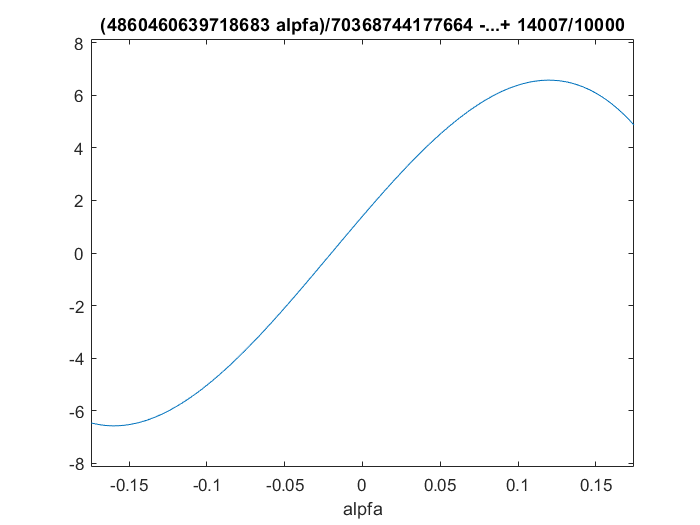

%К(alpfa), c_y(alpfa), c_x(alpfa)
syms alpfa
K=-1202.2026*alpfa^3-72.1322*alpfa^2+69.0713*alpfa+1.4007;
c_y=3.5*alpfa+0.07;
c_x=c_y/K;

ezplot(K,[-10*pi/180,10*pi/180])

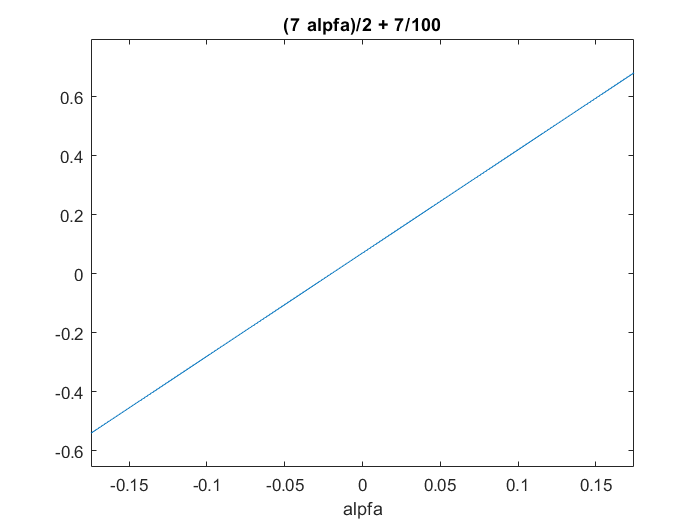

ezplot(c_y,[-10*pi/180,10*pi/180])

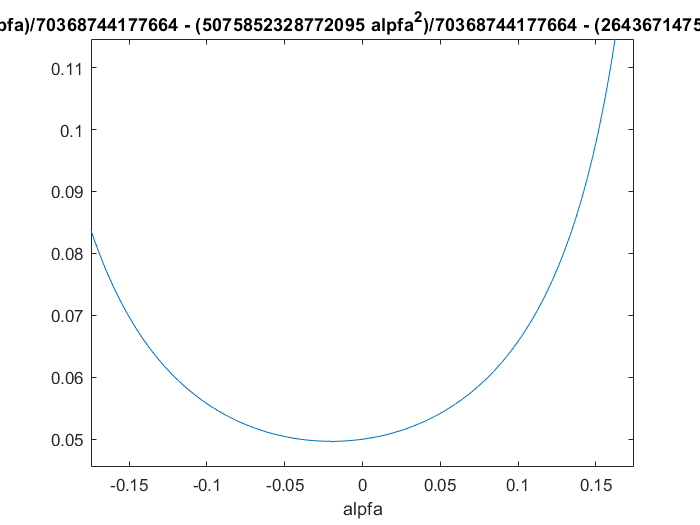

ezplot(c_x,[-10*pi/180,10*pi/180])

Данные о ЛА, необходимые для расчета:

% Исходные данные о ЛА
syms fi_p u

theta=0; % угол наклона траектории = 0, горизонтальный полет
alpfa=5*pi/180; % угол атаки, рад

g=9.81; % ускорение свободного падения, м/с^2
rho=1; % плотность воздуха на высоте 2000м, кг/м^3

K=-1202.2026*alpfa^3-72.1322*alpfa^2+69.0713*alpfa+1.4007; % аэродинамическое качество
c_y=3.5*alpfa+0.07; % аэродинамический коэффициент подъемной силы
c_x=c_y/K; % аэродинамический коэффициент лобового сопротивления

m_p=1; % коэффициент профильного сопротивления
c_o=0.095; % коэффициент тяги винта (выполняется:P1_max=1100, omega_max=300)

m=800; % максимальная взлетная масса, кг
S=10; % площадь крыла, м^2
Y_a=m*g; % потребная подъемная сила

P_max=8800; % максимальная тяга: 8*110кгс=880кгс=8800Н
n=8; % число двигателей ВМГ
R=0.75; % радиус каждого винта ВМГ
omega_max=300; % максимальная угловая скорость вращения лопасти винта ВМГ, рад/c
KPD=0.7; % КПД=70%

Аналитическое вычисление X_a, P и V для определения зависимости индуктивной скорости от угла отклонения ВМГ: u_i(fi_p)

%
X_a=(sin(fi_p-alpfa)*m*g*cos(theta)-cos(fi_p-alpfa)*m*g*sin(theta))/(K*sin(fi_p-alpfa)+cos(fi_p-alpfa));
P=(K*m*g*sin(theta)+m*g*cos(theta))/(K*sin(fi_p-alpfa)+cos(fi_p-alpfa));
V=sqrt((2*X_a)/(c_x*rho*S));
ufi=P/(n*2*rho*pi*R^2*sqrt((V*cos(fi_p-alpfa))^2+(V*sin(fi_p-alpfa)+u)^2))

$$ufi = \begin{array}{l} \frac{872}{\pi \,\sqrt{{\left(u+\sin\left({\mathrm{fi}}_{p}-\frac{\pi }{36}\right)\,\sqrt{\frac{141376999502414610432\,\sin\left({\mathrm{fi}}_{p}-\frac{\pi }{36}\right)}{5561799993361601\,\sigma_{1}}}\right)}^{2}+\frac{141376999502414610432\,{\cos\left({\mathrm{fi}}_{p}-\frac{\pi }{36}\right)}^{2}\,\sin\left({\mathrm{fi}}_{p}-\frac{\pi }{36}\right)}{5561799993361601\,\sigma_{1}}}\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\cos\left({\mathrm{fi}}_{p}-\frac{\pi }{36}\right)+\frac{1711378997857363\,\sin\left({\mathrm{fi}}_{p}-\frac{\pi }{36}\right)}{281474976710656} \end{array}$$

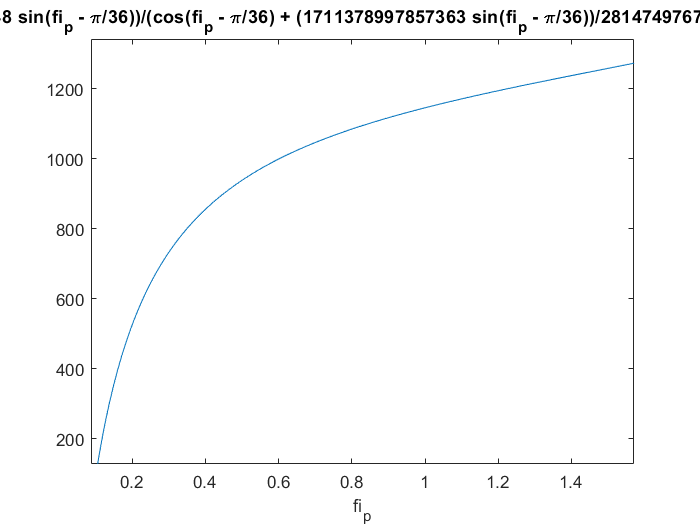


ezplot(X_a,[alpfa,pi/2])

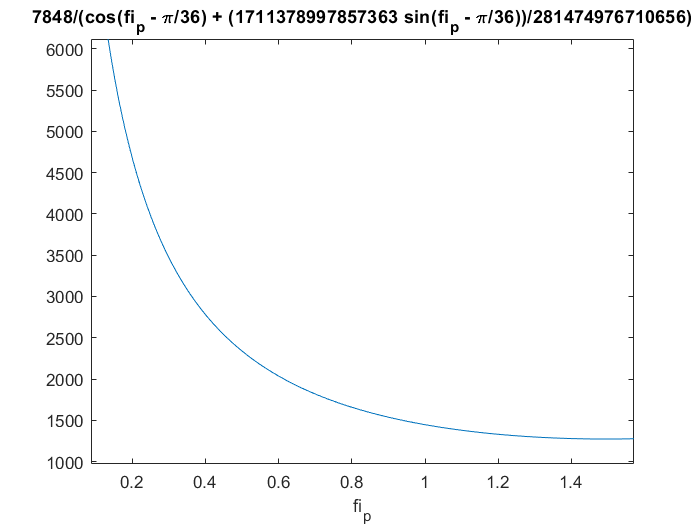

ezplot(P,[alpfa,pi/2])

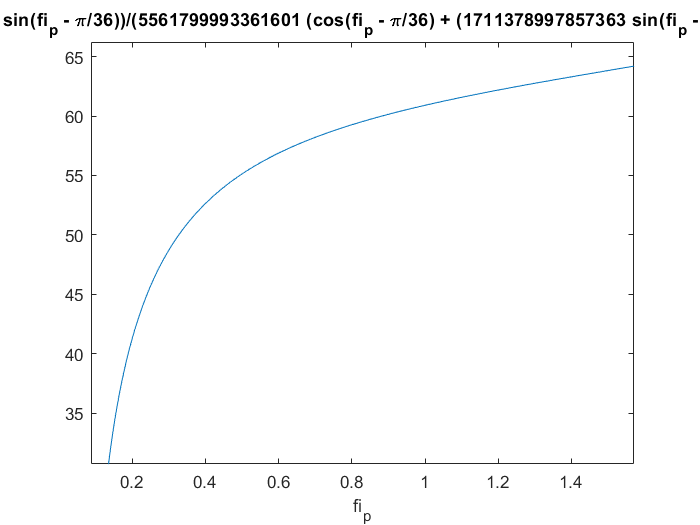

ezplot(V,[alpfa,pi/2])

Численное вычисление u_i(fi_p):

u_i=alpfa*180/pi:1:90;
j=0;
for fi_p=alpfa:1*pi/180:90*pi/180
j=j+1;
u_i(j)=solve(u==872/(pi*((u + sin(fi_p - pi/36)*((141376999502414610432*sin(fi_p - pi/36))/(5561799993361601*cos(fi_p - pi/36) + (9518347698922264905402679318163*sin(fi_p - pi/36))/281474976710656))^(1/2))^2 + (141376999502414610432*cos(fi_p - pi/36)^2*sin(fi_p - pi/36))/(5561799993361601*cos(fi_p - pi/36) + (9518347698922264905402679318163*sin(fi_p - pi/36))/281474976710656))^(1/2)*(cos(fi_p - pi/36) + (1711378997857363*sin(fi_p - pi/36))/281474976710656)),u,'real',true);
end

Зависимости силы сопротивления(X_a), потребной тяги(P), скорости(V), угловой скорости винта(omega) от угла отклонения ВМГ(fi_p):

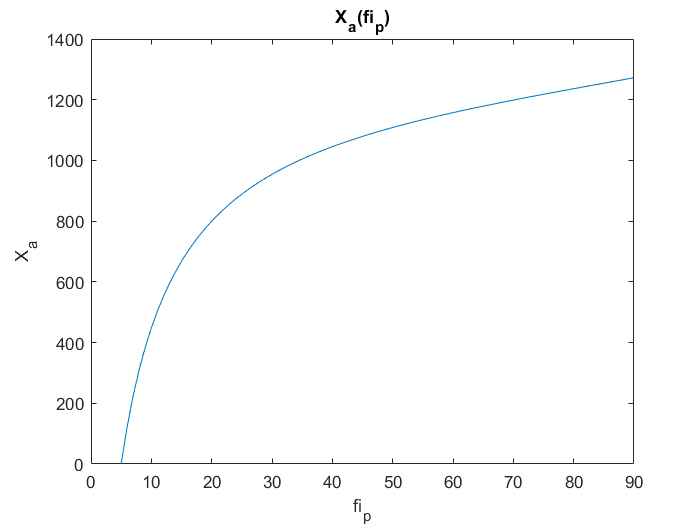

fi_p=alpfa:1*pi/180:90*pi/180; % Изменение fi_p от alpfa до 90 градусов

X_a=(sin(fi_p-alpfa)*m*g*cos(theta)-cos(fi_p-alpfa)*m*g*sin(theta))./(K*sin(fi_p-alpfa)+cos(fi_p-alpfa));
P=(K*m*g*sin(theta)+m*g*cos(theta))./(K*sin(fi_p-alpfa)+cos(fi_p-alpfa));
V=sqrt((2*X_a)/(c_x*rho*S));
omega=sqrt((P*pi^2)/(n*4*c_o*rho*R^4));

plot(fi_p*180/pi,X_a)
title('X_a(fi_p)')
ylabel('X_a')
xlabel('fi_p')

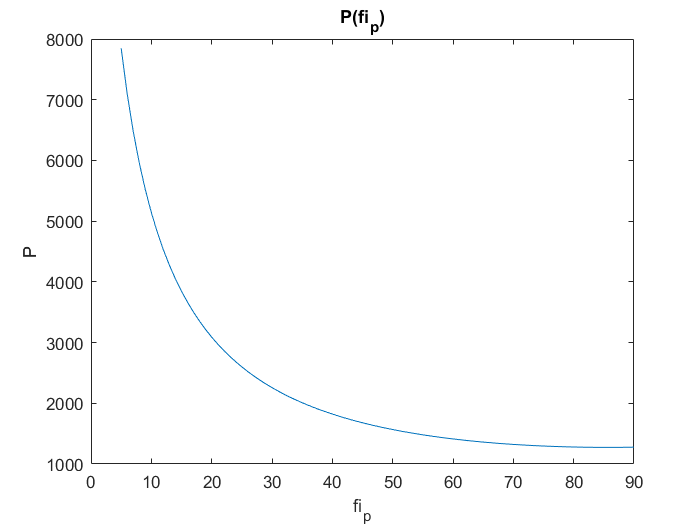


plot(fi_p*180/pi,P)
title('P(fi_p)')
ylabel('P')
xlabel('fi_p')

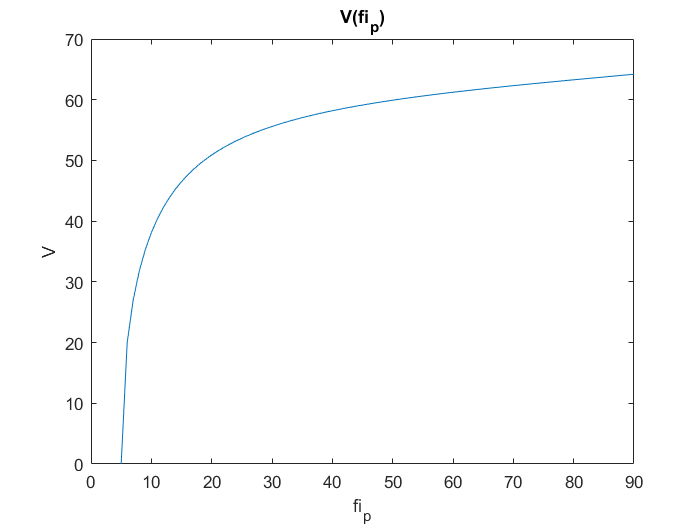


plot(fi_p*180/pi,V)
title('V(fi_p)')
ylabel('V')
xlabel('fi_p')

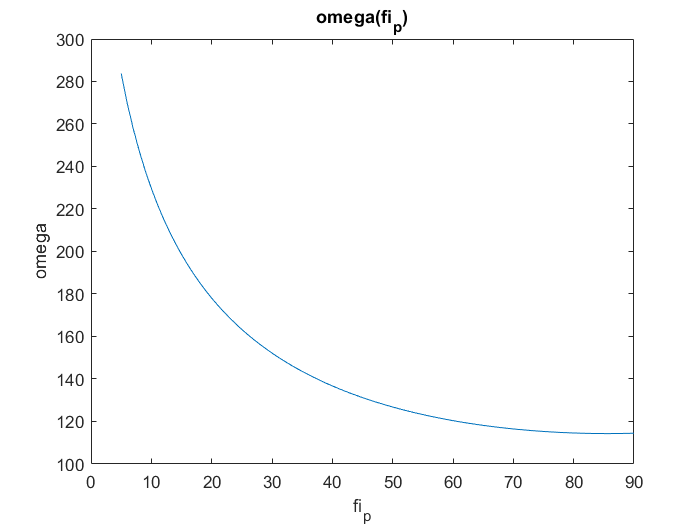


plot(fi_p*180/pi,omega)
title('omega(fi_p)')
ylabel('omega')
xlabel('fi_p')

Требуемая мощность(N_sum) и требуемая мощность ВМГ(N_VMG):

N_sum = P.*V.*sin(fi_p-alpfa) + m_p*(1+4.6*((V.*cos(fi_p-alpfa)./(omega*R)).^2)).*(P.^(1.5))./(sqrt(n*2*rho*pi*R^2))+P.*u_i;
N_VMG = N_sum/KPD;

Наименьший расход энергии в единицу времени:

d(N_VMG)/d(fi_p) = 0

График зависимости N_VMG(fi_p):

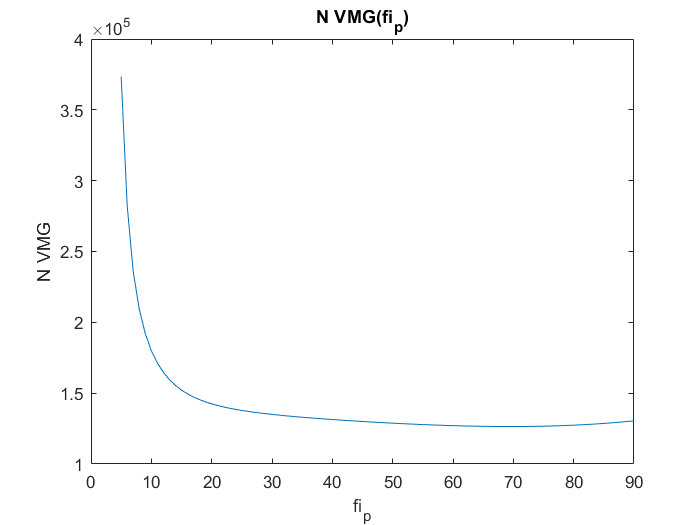

plot(fi_p*180/pi,N_VMG)

title('N VMG(fi_p)')
ylabel('N VMG')
xlabel('fi_p')

N_VMG min=126400 (Вт)

fi_p=70 (град)

Наименьший расход энергии на единицу пройденного пути:

d(N_VMG/V)/d(fi_p) = 0

График зависимости N_VMG/V(fi_p):

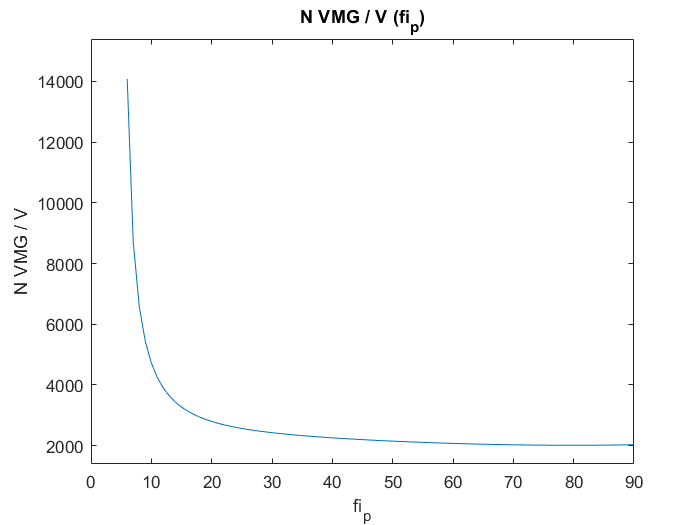

plot(fi_p*180/pi,N_VMG./V)

title('N VMG / V (fi_p)')
ylabel('N VMG / V')
xlabel('fi_p')

N_VMG/V min=2013

fi_p=80 (град)

График зависимости V/N_VMG(fi_p):

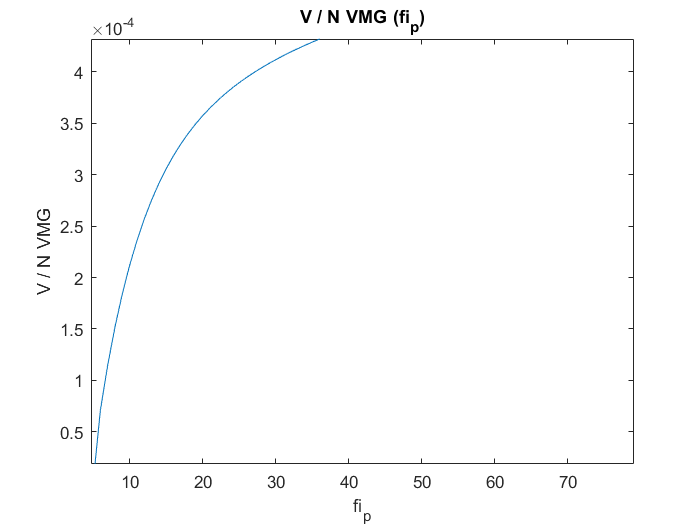

plot(fi_p*180/pi,V./N_VMG)

title('V / N VMG (fi_p)')
ylabel('V / N VMG')
xlabel('fi_p')